# 分布の描画

clear all; clf;
license('inuse')

curve_fitting_toolbox
matlab
statistics_toolbox


## データの準備

### 乱数をデータとして用いる

Q1. 0 から 1までの一様乱数を10000個出力し、変数 data1 に格納せよ。

data1 = rand([1 10000])

data1 =     0.6557    0.0357    0.8491    0.9340    0.6787    0.7577    0.7431    0.3922    0.6555    0.1712    0.7060    0.0318    0.2769    0.0462    0.0971    0.8235    0.6948    0.3171    0.9502    0.0344    0.4387    0.3816    0.7655    0.7952    0.1869    0.4898    0.4456    0.6463    0.7094    0.7547    0.2760    0.6797    0.6551    0.1626    0.1190    0.4984    0.9597    0.3404    0.5853    0.2238    0.7513    0.2551    0.5060    0.6991    0.8909    0.9593    0.5472    0.1386    0.1493    0.2575


Q2. 標準正規分布に従う乱数を10000個出力し、変数 data2 に格納せよ。

data2 = randn([1 10000])

data2 =     0.8087    0.4892   -0.3472    0.3312   -0.8517   -0.6106   -0.6212    0.2070    0.0534   -2.0280   -0.9803   -0.4880   -0.2153   -0.5134    0.6544    1.2959    1.0071    0.3869    1.0825    1.1826    0.5548    1.9956   -0.2529    0.3480   -0.4551   -0.6357   -0.9799   -0.7615   -1.2835   -0.3013   -0.7072    1.5570    0.5279   -1.9343    1.1687   -0.5342   -1.5779    0.5312    1.2251    0.2917    0.4039   -0.7983   -0.1495   -0.0983   -0.2310    0.7332   -0.7730   -0.3223   -0.4475    0.4150


Q3. 平均値 1 の指数分布に従う乱数を10000個出力し、変数 data3 に格納せよ。

pd = makedist('Exponential');
data3 = random(pd, [1 10000])

data3 =     1.9295    0.4848    0.2254    0.1982    0.9980    0.2108    2.8021    2.3996    0.2162    0.6033    0.1108    1.6774    0.1834    2.7704    0.5108    2.8122    1.4544    1.5155    1.3500    0.5120    0.3640    0.0811    0.4222    0.4563    0.9118    1.0277    0.7897    0.1756    0.9416    0.1169    0.2089    0.1957    0.1451    1.0825    2.7604    1.3210    2.3798    0.3985    0.0567    0.4211    0.8762    1.4204    1.0470    0.3570    0.7160    0.1980    1.1088    2.3637    0.1842    0.8517


## 度数分布の描画

Q4. data1 の度数分布を描画せよ。

h1 = histogram(data1)

h1 =   Histogram のプロパティ:

             Data: [0.6557 0.0357 0.8491 0.9340 0.6787 0.7577 0.7431 0.3922 0.6555 0.1712 0.7060 0.0318 0.2769 0.0462 0.0971 0.8235 0.6948 0.3171 0.9502 0.0344 0.4387 0.3816 0.7655 0.7952 0.1869 0.4898 0.4456 0.6463 0.7094 0.7547 … ] (1×10000 double)
           Values: [488 528 502 496 494 501 501 489 493 475 525 513 528 505 491 502 494 496 498 481]
          NumBins: 20
         BinEdges: [0 0.0500 0.1000 0.1500 0.2000 0.2500 0.3000 0.3500 0.4000 0.4500 0.5000 0.5500 0.6000 0.6500 0.7000 0.7500 0.8000 0.8500 0.9000 0.9500 1]
         BinWidth: 0.0500
        BinLimits: [0 1]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  すべてのプロパティ を表示


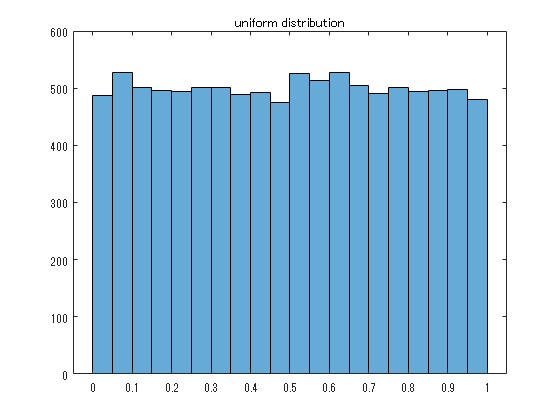

title('uniform distribution')

Q5. data2 の度数分布を描画せよ。

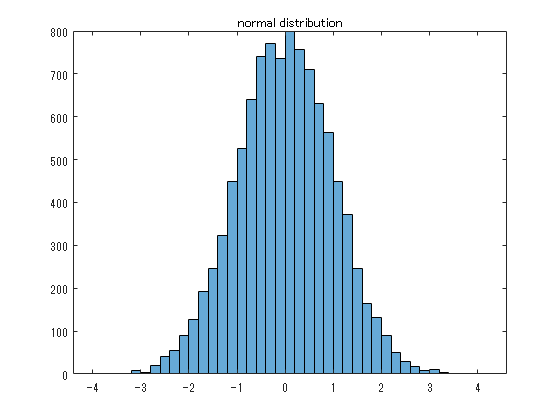

h2 = histogram(data2);
title('normal distribution')

d2 = h2.Values;
x2 = h2.BinEdges(1:end-1)+0.5*h2.BinWidth;


%% 近似: '新規近似 1'。
[xData, yData] = prepareCurveData( x2, d2 );

% 近似タイプとオプションを設定します。
ft = fittype( 'gauss1' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.Lower = [-Inf -Inf 0];
opts.StartPoint = [120 11 2.4910787756085];

% モデルをデータに近似します。
[fitresult, gof] = fit( xData, yData, ft, opts )

fitresult =      一般モデル Gauss1:
     fitresult(x) =  a1*exp(-((x-b1)/c1)^2)
     係数 (95% の信頼限界):
       a1 =       800.3  (787.6, 812.9)
       b1 =    0.006103  (-0.01221, 0.02442)
       c1 =       1.415  (1.389, 1.441)

gof = フィールドをもつ struct :
           sse: 8.8185e+03
       rsquare: 0.9973
           dfe: 38
    adjrsquare: 0.9971
          rmse: 15.2337


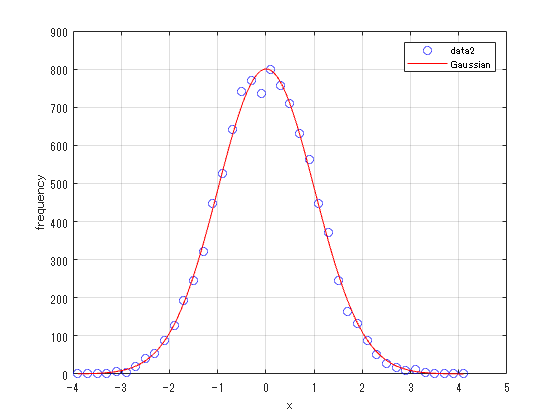


% データの近似をプロットします。
figure( 'Name', '新規近似 1' );
h = plot( fitresult, xData, yData, 'bo' );
legend( h, 'data2', 'Gaussian', 'Location', 'NorthEast', 'Interpreter', 'none' );
% ラベル Axes
ylabel( 'frequency', 'Interpreter', 'none' );
grid on

Q6. data3 の度数分布を描画せよ。

h3 = histogram(data3)

h3 =   Histogram のプロパティ:

             Data: [1.9295 0.4848 0.2254 0.1982 0.9980 0.2108 2.8021 2.3996 0.2162 0.6033 0.1108 1.6774 0.1834 2.7704 0.5108 2.8122 1.4544 1.5155 1.3500 0.5120 0.3640 0.0811 0.4222 0.4563 0.9118 1.0277 0.7897 0.1756 0.9416 0.1169 … ] (1×10000 double)
           Values: [1794 1469 1212 956 844 643 584 441 350 311 252 220 193 130 112 72 74 59 49 41 38 30 23 21 16 14 11 6 4 5 4 4 2 2 2 0 4 4 2 0 0 0 0 1 0 0 0 1]
          NumBins: 48
         BinEdges: [0 0.2000 0.4000 0.6000 0.8000 1 1.2000 1.4000 1.6000 1.8000 2 2.2000 2.4000 2.6000 2.8000 3 3.2000 3.4000 3.6000 3.8000 4 4.2000 4.4000 4.6000 4.8000 5 5.2000 5.4000 5.6000 5.8000 6 6.2000 6.4000 6.6000 6.8000 7 … ] (1×49 double)
         BinWidth: 0.2000
        BinLimits: [0 9.6000]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  

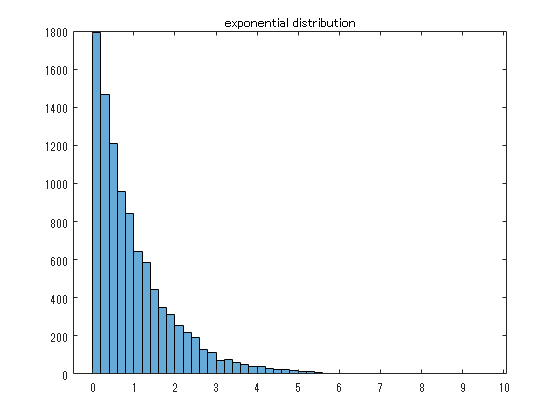

title('exponential distribution')

d3 = h3.Values;
x3 = h3.BinEdges(1:end-1)+0.5*h3.BinWidth;


%% 近似: '新規近似 1'。
[xData, yData] = prepareCurveData( x3, d3 );

% 近似タイプとオプションを設定します。
ft = fittype( 'exp1' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = [358.381349383821 -0.306273949241911];

% モデルをデータに近似します。
[fitresult, gof] = fit( xData, yData, ft, opts )

fitresult =      一般モデル Exp1:
     fitresult(x) = a*exp(b*x)
     係数 (95% の信頼限界):
       a =        1975  (1954, 1995)
       b =     -0.9849  (-0.9995, -0.9703)

gof = フィールドをもつ struct :
           sse: 6.0616e+03
       rsquare: 0.9992
           dfe: 46
    adjrsquare: 0.9992
          rmse: 11.4792


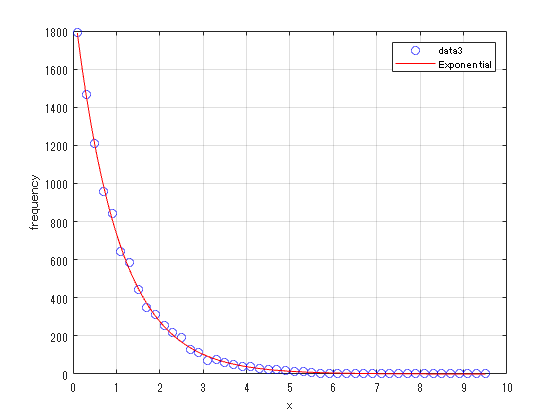


% データの近似をプロットします。
figure( 'Name', '新規近似 1' );
h = plot( fitresult, xData, yData, 'bo' );
legend( h, 'data3', 'Exponential', 'Location', 'NorthEast', 'Interpreter', 'none' );
% ラベル Axes
ylabel( 'frequency', 'Interpreter', 'none' );
grid on

## 演習

Q1. $-1$ から $+1$までの一様乱数を1000個出力し、それらの度数分布を描画せよ。

Q2. 平均 $2$、標準偏差 $3$ の正規分布に従う乱数を1000個出力し、それらの度数分布を描画せよ。

Q3.  平均 10 のポアソン分布に従う乱数を1000個出力し、それらの度数分布を描画せよ。

## 参考文献

- [https://jp.mathworks.com/help/matlab/ref/matlab.graphics.chart.primitive.histogram.html](https://jp.mathworks.com/help/matlab/ref/matlab.graphics.chart.primitive.histogram.html)

- [https://jp.mathworks.com/help/stats/prob.normaldistribution.random.html](https://jp.mathworks.com/help/stats/prob.normaldistribution.random.html)